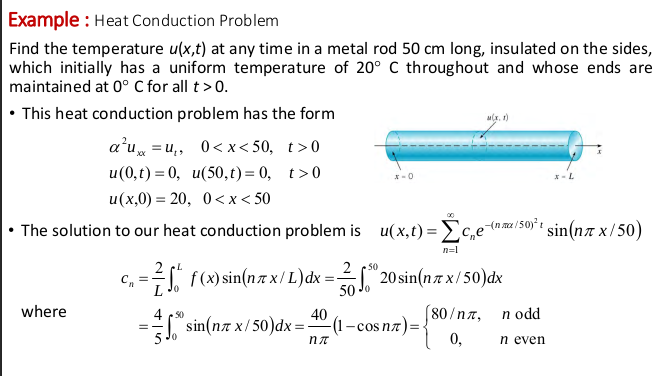

slide4

youtube.com/watch?v=mlCYVEwe6

clear
clf
clc
syms x t u(x,t) L D
assume([L D],"positive")

**Heat equation**

HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

**Boundar

BC0 = u(0,t) == 0;BC=u(L,t)==0

$$BC = u\left(L,t\right)=0$$

**SEPARATION of variables in Heat equation**

syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)=\text{D}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)$$

**Swparation for BC**

BCx0 = subs(BC0,u(0,t),X(0)*T(t))

$$BCx0 = X\left(0\right)\,T\left(t\right)=0$$

**Swparate ODEs introduce constant (Lamda^2)**

var = children(SepVar)

var = 1×2 cell array
    {[X(x)*diff(T(t), t)]}    {[D*T(t)*diff(X(x), x, x)]}


syms lambda
assume(lambda,"positive")
eqT=var(1)==-lambda^2

$$eqT = X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \text{D}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=-\lambda^{2}$$

**Solve ODEs** 

T(t,lambda)=dsolve(eqT)

$$T(t, lambda) = C_{1}-\frac{\lambda^{2}\,t}{X\left(x\right)}$$

X(x,lambda)=dsolve(eqX,BCx0)

**Repllace constant in X**

constantX = setdiff(symvar(X(x,lambda)),sym([]))
X(x,xlambda)= subs(-)